# Plane Elasticity: Quadrangular Meshes

**Example: Constant rigth traction**

The $5\times 2\times 0.05,\mathrm{mm}$ plate shown in the Figure has hole of $1\, \mathrm{mm}$ dimeter, centered  $1\, \mathrm{mm}$ right and $1\, \mathrm{mm}$ up from its lower left corner. The plate is clamped along the hole, whereas its right edge is under a constant traction force of $\tau = 5000\, \mathrm{N/mm}.$ 

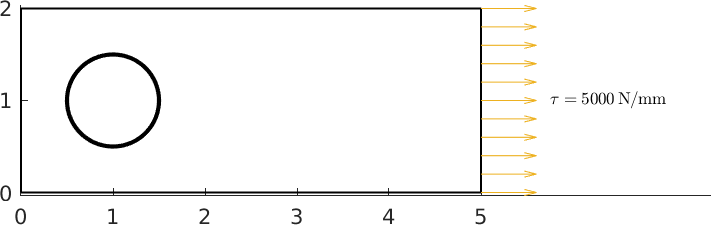

Apply the FEM, using the mesh in `meshPlacaForatQuad.m` to compute the displacements of the nodes, the stress-strain and the von Mises stress. Material properties: Young modulus $E = 10^{7}\, \mathrm{N/mm}^{2}$, Poisson ratio $\nu = 0.3$.

See Toni Susin's Numerical Factory, [FEM course, practice 4.3](https://numfactory.upc.edu/web/FiniteElements/Pract/P10-PlaneElasticity/html/PlaneElasticityQuadMesh.html)

clearvars
close all

excelFileDispl='displacements.xlsx';
excelFileStress = 'stress.xlsx';

%Data
E=1.0e+7;                  %Young Modulus (N/mm^2)
mu=0.3;                    %Poisson's ratio (adimensional)
th=0.05;                   %thickness (in mm)
forceLoad=[5.0e+3; 0.0e0]; %[Fx,Fy] traction force (in N/mm)

modelProblem='stress';

eval('meshPlacaForatQuad');
[numNod,ndim]=size(nodes);
numElem=size(elem,1);
numbering=0;
plotElementsOld(nodes, elem, numbering)
hold on

Select boundary points

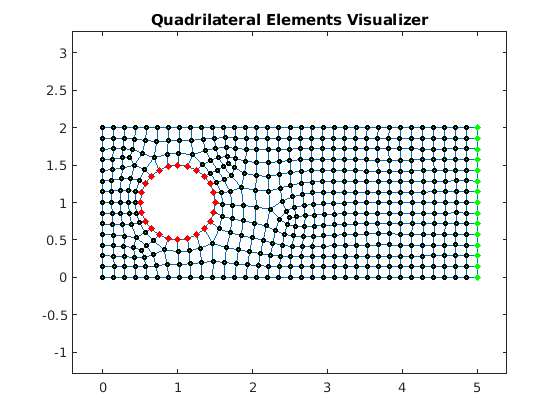

indRight=find(nodes(:,1)>4.99);
indCirc=find(sqrt((nodes(:,1)-1.0e0).^2 + (nodes(:,2)-1.0e0).^2) < 0.51);
 
plot(nodes(indRight,1),nodes(indRight,2),'ok','lineWidth',1,...
    'markerFaceColor','green','markerSize',4,...
    'markerEdgeColor','green')
plot(nodes(indCirc,1),nodes(indCirc,2),'ok','lineWidth',1,...
    'markerFaceColor','red','markerSize',4,...
    'markerEdgeColor','red')
hold off

## Material properties

- `modelProblem == 'srtess'`: plane stress problem (thickness must be specified)

- `modelProblem == 'strain'`: plane strain problem (thickness set to 1)

switch lower(modelProblem)
    case 'stress'
        c11=E/(1-mu^2);
        c22=c11;
        c12=mu*c11;
        c21=c12;
        c33=E/(2*(1+mu));   
    case 'strain'
        th=1;
        c11=E*(1-mu)/((1+mu)*(1-2*mu)); 
        c22=c11;
        c12=c11*mu/(1-mu);
        c21=c12;
        c33=E/(2*(1+mu));
    otherwise
        error('Please, specify whether it''s a ''stress'' or a ''strain'' problem!')
end

C = [c11, c12, 0; c21, c22, 0; 0, 0, c33];

%Computation of the stiffness matrix
K=zeros(ndim*numNod);
F=zeros(ndim*numNod,1);
Q=zeros(ndim*numNod,1);
for e=1:numElem
    Ke=planeElastQuadStiffMatrix(nodes,elem,e,C,th);
    %
    % Assemble the stiffness matrices
    %
    row=[2*elem(e,1)-1; 2*elem(e,1); 2*elem(e,2)-1; 2*elem(e,2); 
         2*elem(e,3)-1; 2*elem(e,3); 2*elem(e,4)-1; 2*elem(e,4)];
    col=row;
    K(row,col)=K(row,col)+Ke;
end

## Natural B.C.

constant traction on the right edge

nodLoads=indRight'; %nodes the traction is applied at
Q=applyLoadsQuad(nodes,elem,nodLoads,Q,forceLoad);

## Essential B.C.

set displacements along the hole to zero

fixedNodes=[ndim*indCirc'-1; ndim*indCirc'];
freeNodes=setdiff(1:ndim*numNod,fixedNodes);
u=zeros(ndim*numNod,1); %initialize the solution to u=0
u(fixedNodes)=0.0;

%Reduced system
%Remark: the linear system is not modified. This is only valid if the BC=0
Km=K(freeNodes,freeNodes);
Qm=Q(freeNodes);

%solve the reduced system
um=Km\Qm;
u(freeNodes)=um;

## Post process

Plot displacements stress-strain and von Mises stress

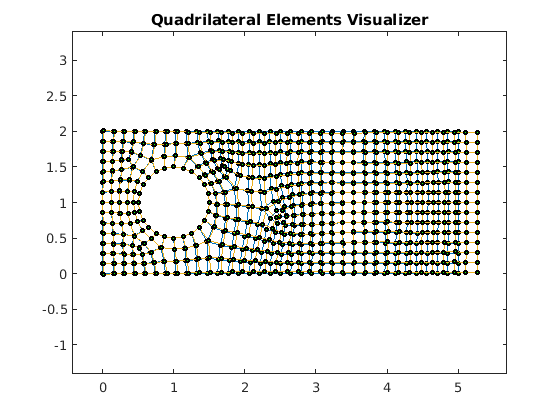

scale=7;
plotPlaneNodElemDespl(nodes, elem, u, scale);

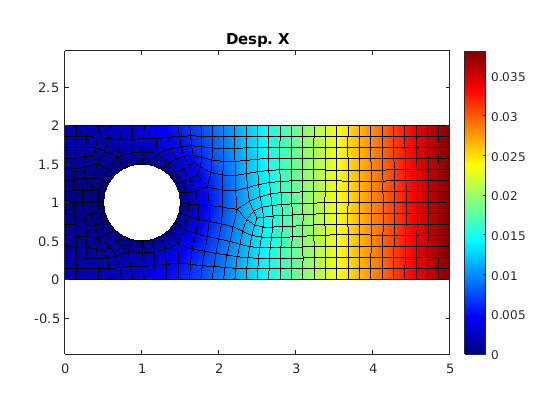


%Contour Solution: Desp.X
valueToShow=u(1:2:end,:);
titol='Desp. X';
colorTable='jet';
plotContourSolution(nodes,elem,valueToShow,titol,colorTable);

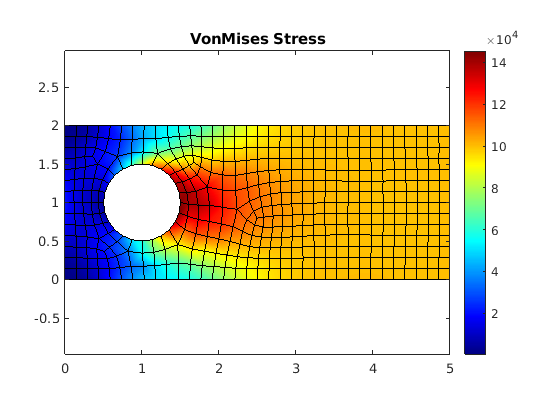


%Compute Strainand StressElement
[stress,vonMises]=computeQuadStrainStressVM(nodes,elem,u,C);

%Plot VM stress
valueToShow=vonMises;
titol='VonMises Stress';
colorTable='jet';
plotContourSolution(nodes,elem,valueToShow,titol,colorTable);

## Post process

Write tables with displacements and stress

format short e
displTable=table((1:numNod)',nodes(:,1),nodes(:,2),...
                  u(1:2:end),u(2:2:end),...
                  'VariableNames',{'NumNod','X','Y','UX','UY'});

%Write table to an Excel file                      
writetable(displTable,excelFileDispl);
%And show the displacements just for the last 10 nodes
displTable(end-9:end,:)

ans = 10×5 table
      NumNod          X             Y             UX            UY     
    __________    __________    __________    __________    ___________
    4.8400e+02    3.0826e+00    9.8769e-01    1.8927e-02    -7.9849e-07
    4.8500e+02    3.2255e+00    9.9261e-01    2.0384e-02    -2.0950e-05
    4.8600e+02    3.3732e+00    9.9580e-01    2.1880e-02    -3.4808e-05
    4.8700e+02    3.5239e+00    9.9835e-01    2.3399e-02    -4.6289e-05
    4.8800e+02    3.6761e+00    9.9985e-01    2.4927e-02    -5.4331e-05
    4.8900e+02    3.8292e+00    1.0002e+00    2.6461e-02    -5.8800e-05
    4.9000e+02    3.9823e+00    9.9958e-01    2.7992e-02    -6.0324e-05
    4.9100e+02    2.5711e+00    6.8164e-01    1.3675e-02     1.1783e-03
    4.9200e+02    2.5346e+00    1.0752e+00    1.3168e-02    -3.2697e-04
    4.9300e+02    2.5


% Table with the stress tensor SX, SY, SXY and von Misses
format short e
stressTable=table((1:numNod)',stress(:,1),stress(:,2),stress(:,3),...
                  vonMises',...
                  'VariableNames',{'NumElem','SX','SY','SXY','VM'});
%Write table to an Excel file                      
writetable(stressTable,excelFileStress);                            
%And show the stress just for the last 10 results
stressTable(end-9:end,:)

ans = 10×5 table
     NumElem          SX            SY             SXY            VM    
    __________    __________    ___________    ___________    __________
    4.8400e+02    1.0169e+05    -2.4469e+03    -1.5848e+02    1.0294e+05
    4.8500e+02    1.0107e+05    -1.7855e+03    -1.0345e+02    1.0197e+05
    4.8600e+02    1.0062e+05    -1.2590e+03    -6.6963e+01    1.0125e+05
    4.8700e+02    1.0031e+05    -8.5886e+02    -4.2946e+01    1.0075e+05
    4.8800e+02    1.0012e+05    -5.6370e+02    -2.6939e+01    1.0041e+05
    4.8900e+02    1.0001e+05    -3.5287e+02    -1.6683e+01    1.0019e+05
    4.9000e+02    9.9956e+04    -2.0816e+02    -1.0097e+01    1.0006e+05
    4.9100e+02    1.0370e+05    -5.2474e+03    -4.3597e+03    1.0669e+05
    4.9200e+02    1.0723e+05    -6.6014e+03     1.1539e+03    1.1070e+05
    4.9300